# Toy problem

This example is a minimal implementation of a continuation procedure. The considered problem is belongs to the test sets of J.R. Cash [1]:


$$\left\lbrace \begin{array}{ll}
\frac{d}{\textrm{dt}}\left(\begin{array}{c}
y_1 \left(t\right)\\
y_2 \left(t\right)
\end{array}\right)=\left(\begin{array}{c}
y_2 \left(t\right)\\
\frac{1}{l}\left(y_1 \left(t\right)+{y_1 \left(t\right)}^2 -\exp \left(\frac{-2x}{\sqrt{l}}\right)\right)
\end{array}\right) & \\
\left(\begin{array}{c}
y_1 \left(0\right)\\
y_1 \left(1\right)-\exp \left(\frac{-1}{\sqrt{l}}\right)
\end{array}\right)=0 & 
\end{array}\;\;\;\;\;\;\;\forall x\in \left\lbrack 0,1\right\rbrack \right.$$


The problem is quite easy to solve for large value of $l$ (e.g. $l=1$) but becomes more and more difficult to solve when $l$ approaches 0. The objective is to compute the solution for a small value of the $l$ parameter, for instance $l={10}^{-4}$.

## Main code

clearvars
close all
clc

### Initial solution

solInit.x=linspace(0,1,10);
solInit.y=repmat([0;0],1,10);

### BVP solver options

In order to reach a high numeric accuracy, we use non default options of the BVP solver.

bvpOpt=bvpset('Nmax',1e4,'AbsTol',1e-6,'RelTol',1e-9);

### Execution of the continuation procedure with a logarithmic scheduler

The scheduler object allows to vary the parameter `l` from its initial value up to its final value. In order to reduce the computation effort, it tries to takes largest step at every iteration. As a result, the new problem to be solved may become quite different from the preceding one and the last computed solution may not be a good initial solution anymore. In that case, the solve may fail. The scheduler will then take a smaller step until the problem can be solved.

Several schedulers are available. Here we use a logarithmic scheduler with default options. We just need to provide the initial and final values of the parameters.

paramStart.l=1; % Initial value of the continuation parameters
paramEnd.l=1e-18; % Final value of the continuation parameters
scheduler=logScheduler(paramStart,paramEnd);

We now define the problem to be solved. Here it corresponds to the BVP described in the begining of this document.

We need to provide several information:

- `"bvp5c"` : a string containing the BVP solver to be used.

- generateFodeFcn : this function generates a handle in the form of `dydt=f(t,y)` for the given continuation parameter values.

- generateBCFcn : this function generates a handle in the form of res=bccond(ya,yb) for the given continuation parameter values. 

-  `bvpOpt` : a structure containing the option of the solver. This parameter is also optional. 

problem=bvp4or5c("bvp5c",@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);

We can now run a continuation procedure to solve the `problem`, using a `scheduler` and starting from a given initial solution `solInit`.

cont=continuationProcedure(problem,scheduler,solInit);
cont.run;

Checking initial solution feasability
Done (initial solution is feasible)
 - Iter : 001 Lambda : 1.0000e+00 delta : 1.00e-01

 - Iter : 002 Lambda : 9.5238e-02 delta : 9.52e-02

 - Iter : 003 Lambda : 8.6384e-03 delta : 9.07e-02

 - Iter : 004 Lambda : 7.4622e-04 delta : 8.64e-02

 - Iter : 005 Lambda : 6.1391e-05 delta : 8.23e-02

 - Iter : 006 Lambda : 4.8102e-06 delta : 7.84e-02

 - Iter : 007 Lambda : 3.5894e-07 delta : 7.46e-02

 - Iter : 008 Lambda : 2.5509e-08 delta : 7.11e-02

 - Iter : 009 Lambda : 1.7266e-09 delta : 6.77e-02



sol=cont.sol;
fprintf('Continuation procedure done\n');

Continuation procedure done


As we used a logarithmic schedule, the requested final value of the parameter is not reached, the algorithm only converges asymptotically toward the final value. The actual final value reached is available in the status variable.

finalL=scheduler.lambda;
fprintf('Actual value of the final parameter : %.5e',finalL);

Actual value of the final parameter : 1.11297e-10

## Compute exact solution

For this simple problem, the exact solution is known:


$$y_{\textrm{exact}} \left(t\right)=\exp \left(\frac{-x}{\sqrt{l}}\right)$$


In order to validate the obtained numerical solution, the exact value is computed over the numerical solution mesh

yExact=exp(-sol.x/sqrt(finalL));

## Display final solution

Both the numerical solution and the exact one are plotted along with their deviation.

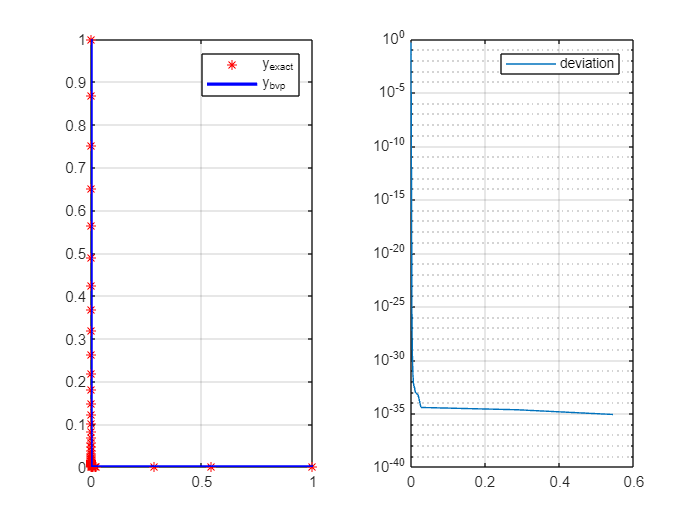

figure;
tiledlayout(1,2);
nexttile;
plot(sol.x,yExact,'r*')
hold on;
plot(sol.x,sol.y(1,:),'b','linewidth',2);
grid on;
legend('y_{exact}','y_{bvp}')
nexttile;
semilogy(sol.x,abs(yExact-sol.y(1,:)));
grid on
legend('deviation')

### `Solution with a single bvp`

`bvp5c` solver is not able to compute a solution to this problem when starting from the provided initial solution. It does not reach the requested tolerance and the provided solution is completely wrong.

This illustrates that the continuation procedure was a convenient way to tackle this problem. Note that the `bvp4c` solver would generate a "singular jacobian" error and that the continuation procedure would be working.

fprintf('Trying to solve the problem using a single BVP problem\n')

Trying to solve the problem using a single BVP problem


bcond=@(ya,yb) myBcfun(ya,yb,finalL);
fode=@(x,y) myOdeFun(x,y,finalL);
solBVP1=bvp5c(fode,bcond,solInit,bvpOpt);

We can now display the obtained accuracy

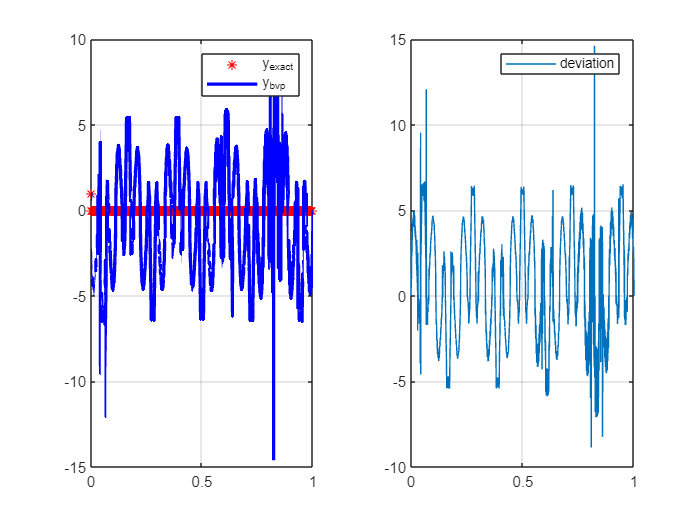

yExact2=exp(-solBVP1.x/sqrt(finalL));

figure;
tiledlayout(1,2);
nexttile;
plot(solBVP1.x,yExact2,'r*')
hold on;
plot(solBVP1.x,solBVP1.y(1,:),'b','linewidth',2);
grid on;
legend('y_{exact}','y_{bvp}')
nexttile;
plot(solBVP1.x,yExact2-solBVP1.y(1,:));
grid on
legend('deviation')

## Definition of the problem to be solved

The `myOdeFun` corresponds to the dynamics of the boundary value problem to be solved. `x` represent the independent variable (time) and `y` the system state to be integrated. The output `dydx` corresponds to the dynamics of the system to be integrated.

function dydx = myOdeFun(x,y,l)
% system dynamics
 dydx = [y(2);
        (y(1)*(1++y(1))-exp(-2*x/sqrt(l)))/l];

end

The `myBcfun` computes the residual of the boundary value according to the initial state `ya` and final state `yb`. When all the components of `res` are equal to 0, then the problem is perfectly solved.

function res = myBcfun(ya,yb,l)
% Boundary condition
  res=[ya(1)-1;
      yb(1)-exp(-1/sqrt(l))];
end

## Definition of functions needed by the continuation procedure

The `generateFodeFcn` function generates a handle to a function in the form of `dydx=f(x,y)` requested by BVP solvers. This handle is built by calling a custom function with some continuation parameters `continuationParams` (computed by the scheduler) and some fixed parameters `fixedParams` (additionnal parameters that may be required and that does not vary during the continuation procedure).

function fode=generateFodeFcn(continuationParams,fixedParams)
% Retrieve parameters "l" in the function workspace from the continuation 
% procedure & fixed parameters
retrieveContinuationParameters({continuationParams,fixedParams});
% Build a handle to the BVP dynamics
fode=@(x,y) myOdeFun(x,y,l);
end

The `generateBCFcn` function generates a handle to a function in the form of res`=bccond(ya,tb)` requested by BVP solvers to represet the boundary condition. This handle is built by calling a custom function with some continuation parameters `continuationParams` (computed by the scheduler) and some fixed parameters `fixedParams` (additionnal parameters that may be required and that does not vary during the continuation procedure).

function bcond=generateBCFcn(continuationParams,fixedParams)
% Retrieve parameters "l" in the function workspace from the continuation 
% procedure & fixed parameters
retrieveContinuationParameters({continuationParams,fixedParams});
% Build a handle to the boundary condition function
bcond=@(ya,yb) myBcfun(ya,yb,l);
end

## Reference

1 Mazzia, F., Cash, J.R.: A fortran test set for boundary value problem  solvers. AIP Conference Proceedings 1648(1), 020009 (2015).  https://doi.org/10.1063/1.4912313.  url:  [https://archimede.uniba.it/~bvpsolvers/testsetbvpsolvers/](https://archimede.uniba.it/~bvpsolvers/testsetbvpsolvers/)